# Whale Path Visualization

This script animates the logged movement of a single whale.

## Load the data

load cleanWhaleData whales

Select a single whale from the dataset.

id = "2006CA-Bmu-23039";
rowsToKeep = whales.ID==id;
whale = whales(rowsToKeep,:)

whale = 121×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    2006CA-Bmu-23039    2006-10-09 12:18:46.000     -116.85      31.625           1                  4             argos-doppler-shift          ""      
    2006CA-Bmu-23039    2006-10-09 12:51:52.000     -116.85       31.64           A                  3             argos-doppler-shift          ""      
    2006CA-Bmu-23039    2006-10-09 23:43:23.000     -116.88      31.606           0            

Plot the whale's travels.

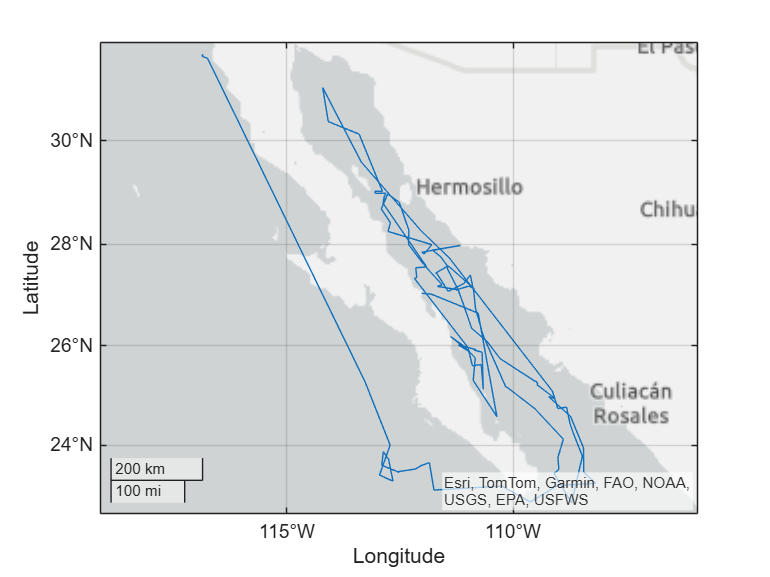

geoplot(whale.latitude,whale.longitude)

## Animate Whale's Travels

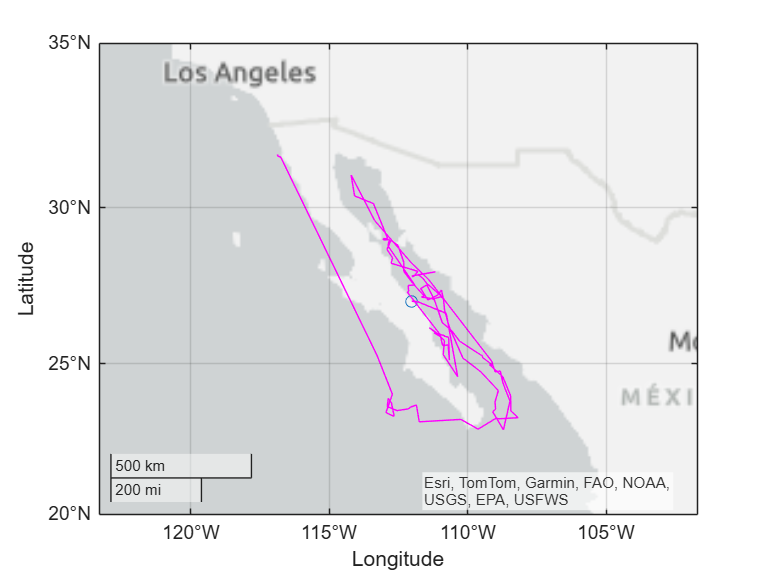

for ai = 1:height(whale)
    geoplot(whale.latitude(ai),whale.longitude(ai), "o")
    hold on
    geoplot(whale.latitude(1:ai), whale.longitude(1:ai), "m")
    hold off
    geolimits([20 35], [-115 -110])
    drawnow
end